# **demo03 of Im2mesh package**

demo03 - Demonstrate how to export mesh as inp, bdf, and .node/.ele file

Author: Jiexian Ma

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D. We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Circle

Let's start demo. First, we'll use function im2mesh to generate mesh. In the next step, we'll export the mesh.

Import image Circle.tif.

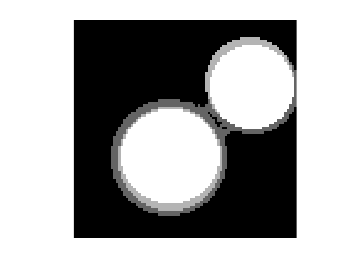

im = imread("Circle.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.tf_avoid_sharp_corner = true;
opt.threshold_num_turning = 10;
opt.threshold_num_vert_Smo = 20;
opt.threshold_num_vert_Sim = 20;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                352                438
         10                378                797
         14                378                881


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          8                507                438
         10                515               1321
         19                522               2463


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                526               2443
          8                100               2443



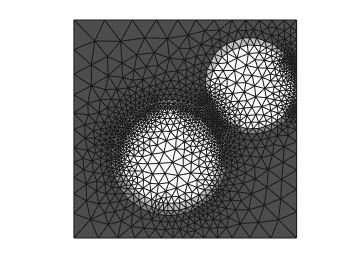

plotMeshes( vert, tria, tnum )

## Prepare for mesh export

Setup parameters.

% parameters for mesh export
dx = 1; dy = 1;     % scale of your imgage
                    % dx - column direction, dy - row direction
                    % e.g. scale of your imgage is 0.11 mm/pixel, try
                    %      dx = 0.11; and dy = 0.11;
                    
ele_order = 1;      % for getNodeEle, this variable is either 1 or 2
                    % 1 - linear / first-order element
                    % 2 - quadratic / second-order element
                    % Note: printBdf only support linear element
                    % Note: when ele_order=2 may have bugs. I'll fix later
                    
ele_type = 'CPS3';  % element type, for printInp

precision_nodecoor = 8; % precision of node coordinates, for printInp
                        % e.g. precision_nodecoor=4, dx=1 -> 0.5000 
                        %      precision_nodecoor=3, dx=0.111, -> 0.055

Obtain node coordinares and elements from mesh.

% scale node coordinates
vert( :, 1 ) = vert( :, 1 ) * dx;
vert( :, 2 ) = vert( :, 2 ) * dy;

% get node coordinares and elements from mesh using function getNodeEle
[ nodecoor_list, nodecoor_cell, ele_cell ] = getNodeEle( vert, tria, ...
                                                    tnum, ele_order );

[ nodecoor_list, nodecoor_cell, ele_cell ] is an alternative way to represent the triangular mesh. The format is useful for importing the mesh into commercial finite element software. The meaning of these three variable is as follows.

nodecoor_list is node coordinates, N-by-3 array.

nodecoor_cell is a 1-by-P cell array. nodecoor_cell{i} represents the node numbering and node coordinates in the i-th phase.

ele_cell is a 1-by-P cell array. ele_cell{i} represent elements in the i-th phase.

We will write these three variables nodecoor_list, nodecoor_cell, ele_cell to inp, bdf, and .node/.ele file. 

## Export

Export mesh as inp, bdf, and .node/.ele file. The files will be saved to current folder.

% write file
% inp file (Abaqus)
% print as multiple parts
printInp_multiPart( nodecoor_cell, ele_cell, ele_type, precision_nodecoor );

printInp_multiPart Done! Check the inp file!


% print as multiple sections
printInp_multiSect( nodecoor_list, ele_cell, ele_type, precision_nodecoor );

printInp_multiSect Done! Check the inp file!



% bdf file (Nastran bulk data)
printBdf( nodecoor_list, ele_cell, precision_nodecoor );

printBdf Done! Check the bdf file!



% .node/.ele file 
% haven't been tested
printTria( vert, tria, tnum, precision_nodecoor );  

printTria Done! Check .node and .ele file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo